% Clear all figures
close all;

colorList = ["r" "g" "b" "c" "m" "#EDB120" "k" "#EbB120"];

% Define directory containing the audio files
directory = 'ESP32/cppstreamer/bioncodetest';
filename = fullfile(directory, 'num_0');

%allMics = zeros(1,8);
fileID = fopen(filename);
data = fread(fileID,'single');

% Create a tiled layout for the subplots
t_layout = tiledlayout(8, 2);
sampleRate = 41666;
numSamples = 190;
numMics = 8;
micList = 0:7;
allAudio = cell(numMics, 1);
aos = zeros(8,1);

% Loop through each audio file
for m = 1:8
    % Construct file name
    filename = fullfile(directory, sprintf('mic_%d.wav', i));
    
    onePacketLength = numSamples*numMics ;
    numPacketsInData = floor(length(data)/onePacketLength);
    micData = zeros(numSamples,1);
    for i = 0:numPacketsInData-1
        micData = [micData; data(1+(micList(m)*numSamples)+i*onePacketLength:(micList(m)*numSamples)+i*onePacketLength+numSamples)];
    end

    % Read audio file
    micData = micData((numSamples+1):8*sampleRate);
    audio = micData;
    allAudio{m} = micData;
     
    
    % Time vector
    t = (0:length(audio)-1) / 41666;
    
    % Create the next tile in the tiled layout
    nexttile;
    % Plot audio
    plot(t(99300:102800), audio(99300:102800), LineWidth=2, Color=colorList(m));
    %plot(t(84650:84720), audio(84650:84720), LineWidth=2, Color=colorList(m));
    [mag, index] = max(audio(94300:94800));
    hold on
    sprintf('%.20f,',t(94300+index))
    aos(m) = t(84650+index);
    %xline(t(84650+index))
    hold off
    grid on



    if m == 7
        xlabel('Time (s)', 'FontSize', 8);
    end
    if m~=7
        xticklabels([]);
    end
    ylim([-1.5*power(10, 8) 1.5*power(10, 8)])
    ylabel('Amplitude', 'FontSize', 8);
    title(sprintf('Q_%d', m-1), 'FontSize', 8);

    % Calculate FFT
    N = length(audio(95300+index:end));
    Y = fft(audio(95300+index:end));
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = sampleRate*(0:(N/2))/N;
    
    % Create the next tile in the tiled layout
    nexttile;
    
    % Plot FFT
    plot(f, mag2db(P1)-max(mag2db(P1)), LineWidth=2, Color=colorList(m));
    grid on

    %ytickList = linspace(0, 4e7,5);
    %yticks(ytickList(1:1:end))
    %yticklabels(string(ytickList(1:1:end)/10e6)+'e7')
    xtickList = linspace(0,2e3,5);
    xticks(xtickList(1:1:end))
    xticklabels([]);
    ylim([-100 0]);

    if m == 7
        xlabel('Frequency (Hz)', 'FontSize', 8);
        xticklabels(string(xtickList(1:1:end)))
    end
    if m~=7
        %xticklabels([]);
        
    end
    ylabel('Magnitude', 'FontSize', 8);
    xlim([1 2000])
    %ylim([0 4*power(10, 7)])
    
    title(sprintf('Q_%d', m-1), 'FontSize', 8);
    
end

ans = '2.26429222867565860255,'

ans = '2.26923630778092455529,'

ans = '2.26921230739691814904,'

ans = '2.26724427590841459690,'

ans = '2.27518840301444802421,'

ans = '2.27521240339845443046,'

ans = '2.26729227667642696531,'

ans = '2.27055632890126224410,'


theMax = min(aos);
aos = aos - theMax

aos =          0
    0.0049
    0.0049
    0.0030
    0.0109
    0.0109
    0.0030
    0.0063


for m=1:7
    sprintf('%.20f,',aos(m))
end

ans = '0.00000000000000000000,'

ans = '0.00494407910526550864,'

ans = '0.00492007872125954648,'

ans = '0.00295204723275555025,'

ans = '0.01089617433878942165,'

ans = '0.01092017472279538381,'

ans = '0.00300004800076791867,'

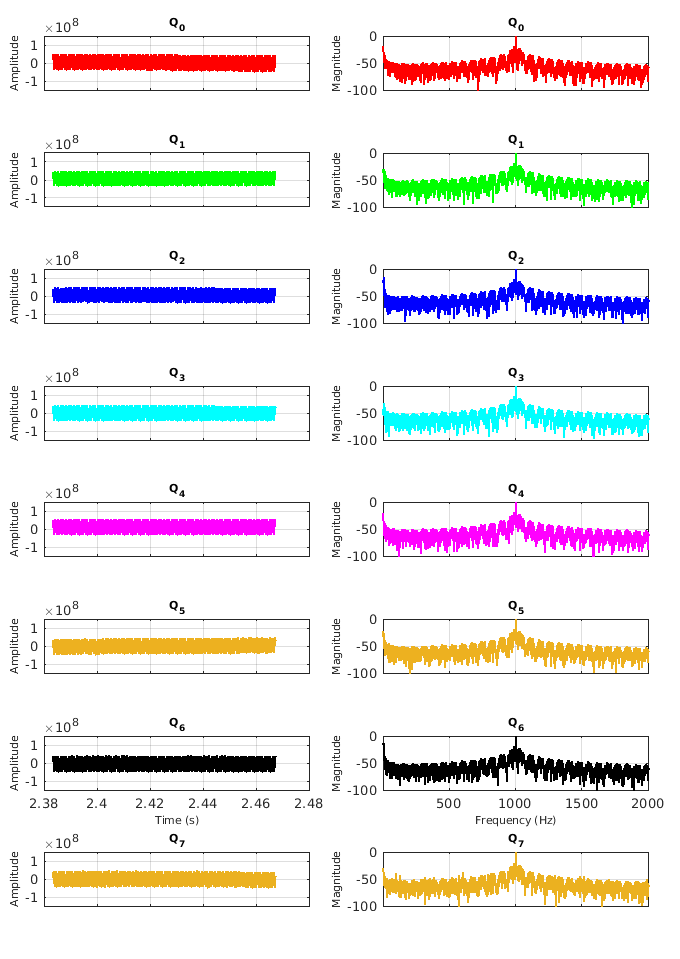




t_layout.TileSpacing = 'compact';
t_layout.Padding = 'compact';

% Adjust the figure size
set(gcf,'Visible','on', 'Units', 'centimeters','OuterPosition', [0 0 18 30])

% Export the figure to PDF
exportgraphics(gcf,'wavSanity.pdf')